- Genere una señal senoidal portadora de 20Hz y una señal de información cosenoidal moduladora de 2 Hz. 

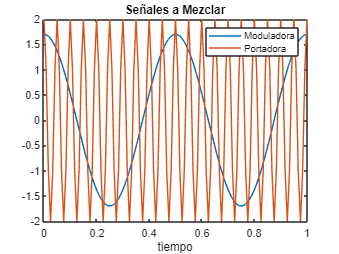

%Parametros
kps_64      =                 120;            %Muestreo Nyquist 4 veces la freq de la portadora
time        =        0:1/kps_64:1;  %Tiempo de Muestreo
time_am     =        -.5:1/120:.5;
%señal Portadora
ap          =                2;
freq_port   =               20;            %Frecuencia de Portadora
wp          =   2*pi*freq_port;
port_sig    =  ap*cos(wp*time);
%señal moduladora
am          =             1.7;
freq_mod    =               2;            %Frecuencia de Moduladora
wm          =   2*pi*freq_mod;
mod_sig     =   am*cos(wm*time); %porque + tiempo y no *tiempo?
% Señales en tiempo
figure(1);
plot(time, mod_sig)
hold on
plot(time, port_sig)
title('Señales a Mezclar');
xlabel('tiempo')
legend({'Moduladora','Portadora'},'Location','northeast')
hold off

## Modulacion AM Convencional 

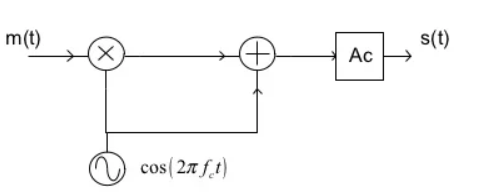

El indice de modulacion $\beta$ esta dado por la siguiente relacion


$$\beta =\frac{A_m }{A_p }$$


donde **Am** es la amplitud de la señal moduladora y **Ap** es la amplitud de la señal portadora.

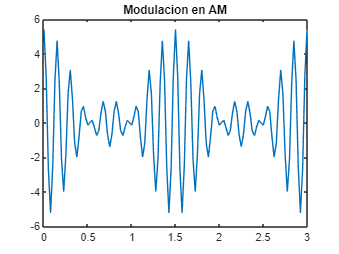

index_mod   =       am/ap;
%   Multiplicador de Señal Portadora y Modulada
%am_sig      =       am*mod_sig.*port_sig + ap*port_sig;
am_sig      =       port_sig.*mod_sig + port_sig;
figure(2);
plot(time*3, am_sig);
title('Modulacion en AM');

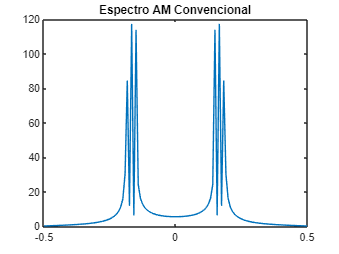

figure(3);
plot(time_am,abs(ttof(am_sig)));
title('Espectro AM Convencional');

## Modulacion AM Doble Banda Lateral con Portadora Suprimida (DBLPS)

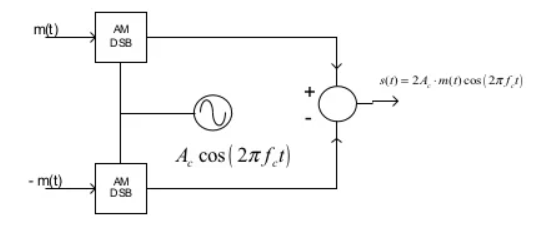

Primero necesitamos desfazar la señal moduladora 180° para tenerla invertida, entonces la multiplicamos un la portadora y al final sumamos las diferencias de las señales para tener la señal deseada

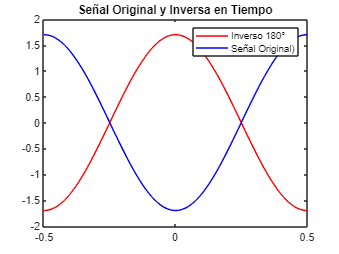

time_dsb    =       -.5:1/120:.5;  %Tiempo de Muestreo
%   Inversion de Moduladora 180°
wm          =   (pi).*freq_mod;     
mod_sig_180 =   am.*-cos(wm*time);                   
mod_sig_0 =   am.*cos((wm)*time);
figure(4)
plot(time_dsb,mod_sig_180,'r',time_dsb,mod_sig_0,'b'); 
legend('Inverso 180°','Señal Original)');
title('Señal Original y Inversa en Tiempo');

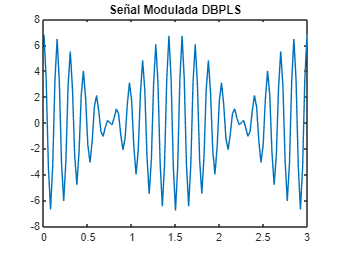

%   Modulador Balanceado 1
mod_bal_01 = mod_sig_0 .* port_sig;
%Modulador Balanceado 2
mod_bal_02 = mod_sig_180 .* port_sig;
%   Diferencia de Señales
sig_am_dsbsc = mod_bal_01 - mod_bal_02;
plot(time*3,sig_am_dsbsc); 
title('Señal Modulada DBPLS');

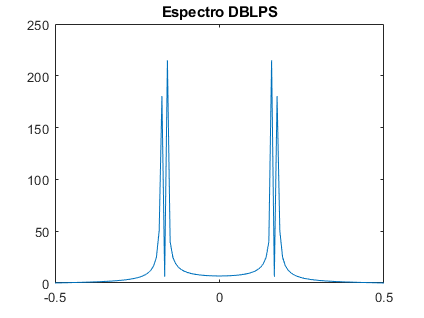

figure(8)
plot(time_dsb,abs(ttof(sig_am_dsbsc)));
title('Espectro DBLPS');

## Modulacion BLU

Para desfazar una señal antes de que entre al modulador que solo es un multiplicador de señal hay que utilizar por simplicidad la funcion de matlab delayseq, para adelantar o atrasar 90° en tiempo la señal modulada original.

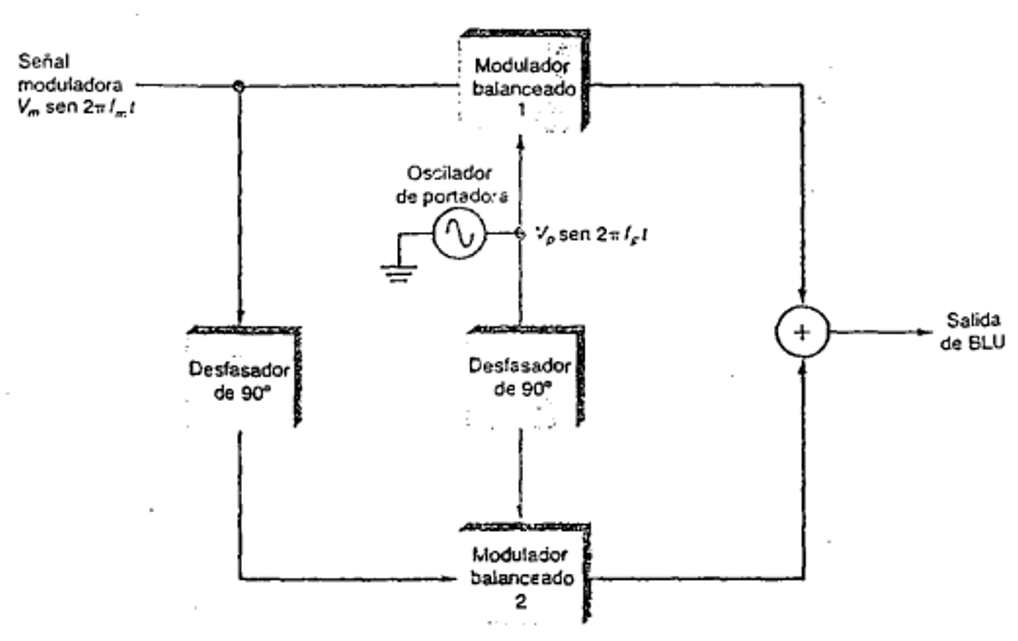

Si bien se puede derivar la señal cos para tener un -seno osea atrasar la señal 90°, si aplico un integrador el coseno me adelanta la señal 90°

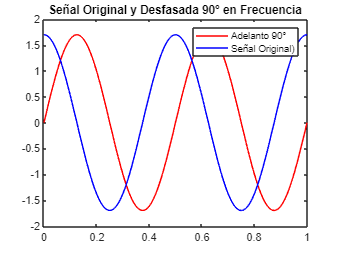

% Desface de Moduladora 90°
wm          =   2*pi*freq_mod;
mod_sig_90     =   am*sin(wm*time);                   % señal adelantada 90°---->porque + tiempo y no *tiempo?
figure(4)
plot(time,mod_sig_90,'r',time,mod_sig,'b'); 
legend('Adelanto 90°','Señal Original)');
title('Señal Original y Desfasada 90° en Frecuencia');

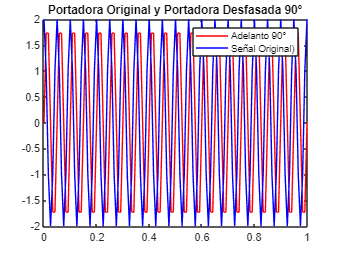

% Desface de Portadora 90°
wp          =   2*pi.*freq_port;
port_sig_90     =   ap.*sin(wp.*time);                   % señal adelantada 90°---->porque + tiempo y no *tiempo?
figure (5);
plot(time,port_sig_90,'r',time,port_sig,'b'); 
legend('Adelanto 90°','Señal Original)');
title('Portadora Original y Portadora Desfasada 90°');

El primer modulador balanceado lo unico que hace es multiplicar la señal moduladora con la señal de la portadora original.

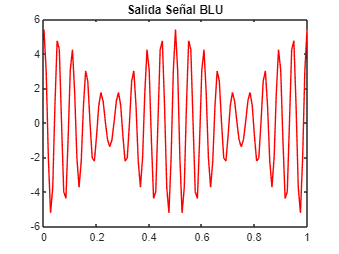

time_blu    =       -.5:1/120:.5;  %Tiempo de Muestreo
% Modulador balanceado 1
mod_bal_1 = am_sig;
% Modulador Balanceado 2
mod_bal_2   = mod_sig_90.*port_sig_90;
% Sumador resultante BLU
BLU_out     = mod_bal_1 + mod_bal_2;
figure (6);
plot(time,BLU_out,'r');
title('Salida Señal BLU');

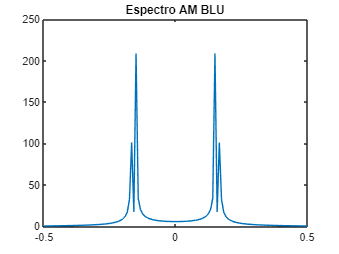

figure(7);
plot(time_blu,abs(ttof(BLU_out)));
title('Espectro AM BLU');

## **Demodulacion Coherente Vs No-Coherente**

Un receptor **Coherente o Sincrono**, es aquel que utiliza frecuencias generadas en el receptor que se usan para la demodulacion, se sincronizan con las frecuencias de un Oscilador generadas en el transmisor.

Un Receptor **No Coherente o de Deteccion de envolvente** porque la informacion se recupera a partir de la onda recibida detectando la envolvente.

## **Demodulacion Envolvente Señal AM**

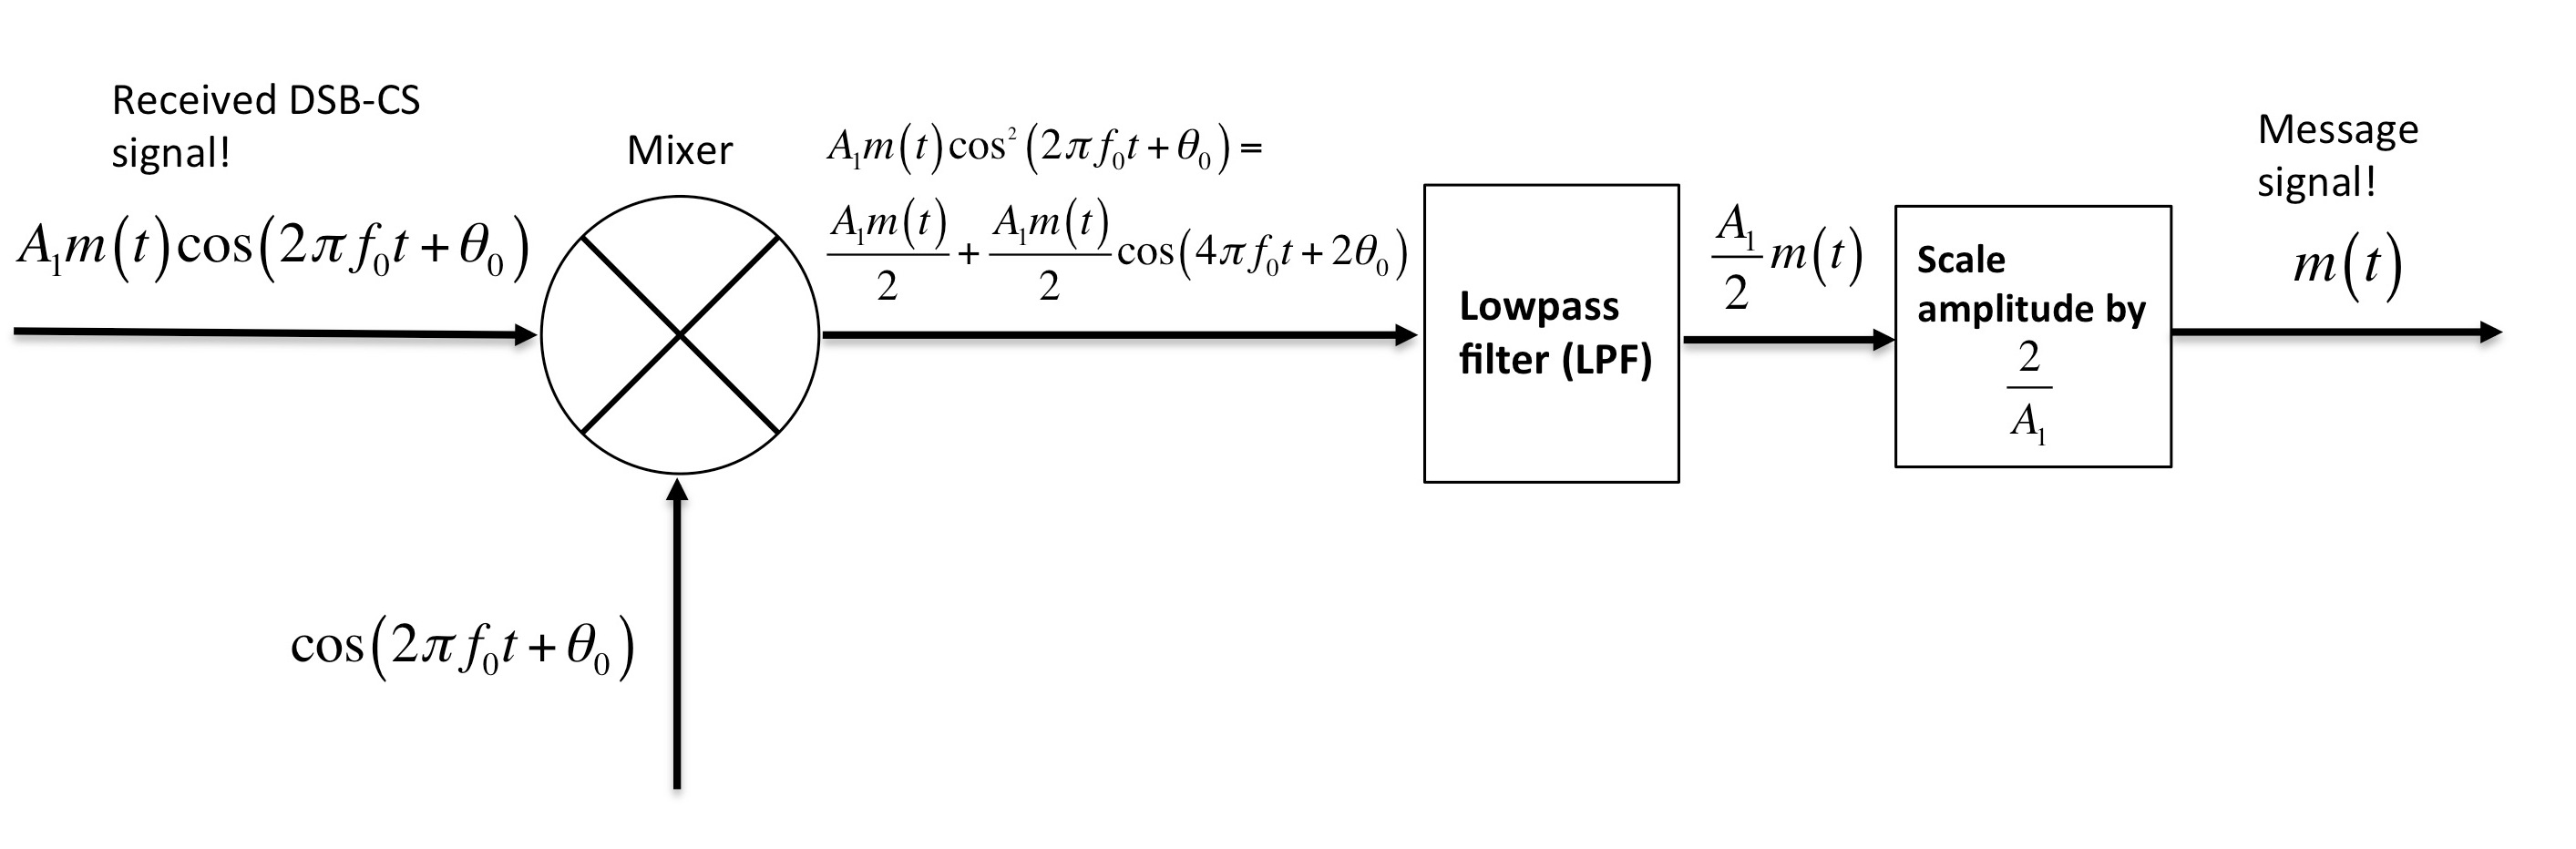

- La señal de recepección es $m(t)cos(w_ct)$

- La señal demodulada es $m(t)cos(w_ct)cos(w_ct)=m(t)cos^2(w_ct)$

- Existe una propiedad trigonometrica [[PAG 4](https://uspas.fnal.gov/materials/11ODU/FourierTransformPairs.pdf)] $cos^2(x) \rightarrow \frac{1}{2}[1+cos(2x)]$

- Por lo tanto la señal queda expandida de esta forma $\frac{m(t)}{2} + m(t) cos(2w_ct)$

- Su transfromada de fourier $\frac{M(\omega)}{2}+\frac{1}{2}[\frac{1}{2}M(\omega-2\omega_c)+\frac{1}{2}M(\omega+2\omega_c)]$

    
$$\frac{M(\omega)}{2}+[\frac{1}{4}M(\omega-2\omega_c)+\frac{1}{4}M(\omega+2\omega_c)]$$


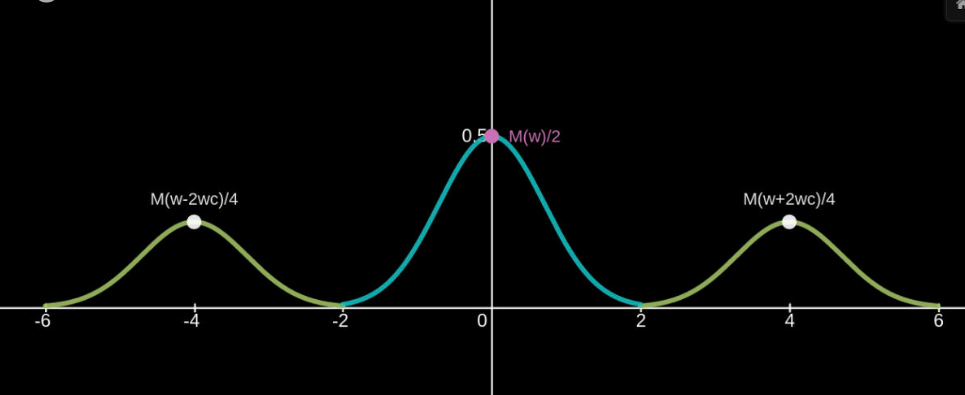

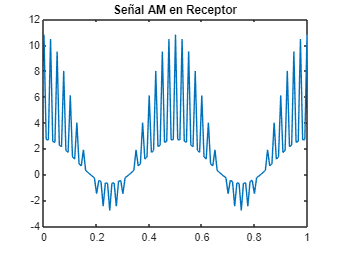

sig_recover = am_sig.*port_sig;
figure (8);
plot(time,sig_recover);
title('Señal AM en Receptor');


$$\frac{M(\omega)}{2}+[\frac{1}{4}M(\omega-2\omega_c)+\frac{1}{4}M(\omega+2\omega_c)]$$


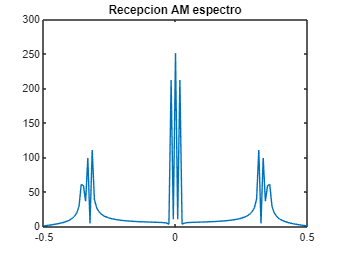

plot(time_am,abs(ttof(sig_recover)))
title('Recepcion AM espectro');

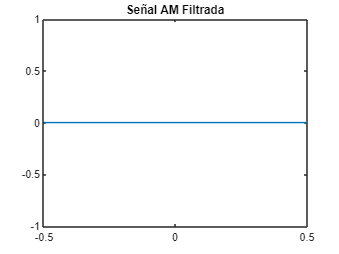

%   Filtrado de Señal Recuperada
filtrof = zeros(1,length(sig_recover));
%filtrof(find(time_am==-20):find(time_am==20))=1;    %AQUI QUE HACE?
% multiplicamos por el filtro en el dominio de la frecuencia
sig_filtered = ttof(sig_recover).*filtrof;
%regresamos la señal al dominio del tiempo
sig_filtered = real(ftot(sig_filtered));
plot(time_am,sig_filtered);
title('Señal AM Filtrada');

## **Demodulacion Coherente Señal AM con Filtrado **

## **Pasabanda Carrier **(Fase Cerrada de Costas)

%   Señal de entrada Señal AM Convencional Normal

%   Multiplicador Entrada Normal y Señal Retro Normal

%   Multiplicador Entrada Normal y Señal Retro Desplazada -90°

%   Filtrado LPF Normal y Desplazada -90°

%   Multiplicador Señales Filtradas

%   Filtrado LPF Señal Multiplicada de Filtradas

%   Salida Demodulada es la Salida del Primer Filtro LPF


## **Demodulacion Coherente **DBLPS con Filtrado pasa bajas (Fase Cerrada de Costas)

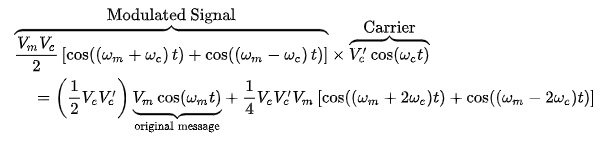

%   Señal de entrada   Señal DBLPS Normal

%   Multiplicador Entrada Normal y Señal Retro Normal

%   Multiplicador Entrada Normal y Señal Retro Desplazada -90°

%   Filtrado LPF Normal y Desplazada -90°

%   Multiplicador Señales Filtradas

%   Filtrado LPF Señal Multiplicada de Filtradas

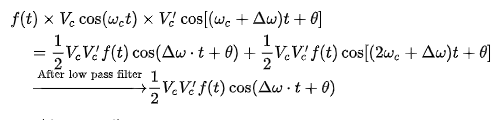

%   Salida Demodulada es la Salida del Primer Filtro LPF

